Q3 a

%parameters
alpha = 0.36;
beta = 0.9;
sig = 0.01;

%input parameters
N = 20;
mu = (1/(1-alpha))*log(alpha*beta);
rho = alpha;
sigma = sig;
m = 3;

%Tauchen
[Z, Zprob] = tauchen(20,mu,rho, sigma,m);


b

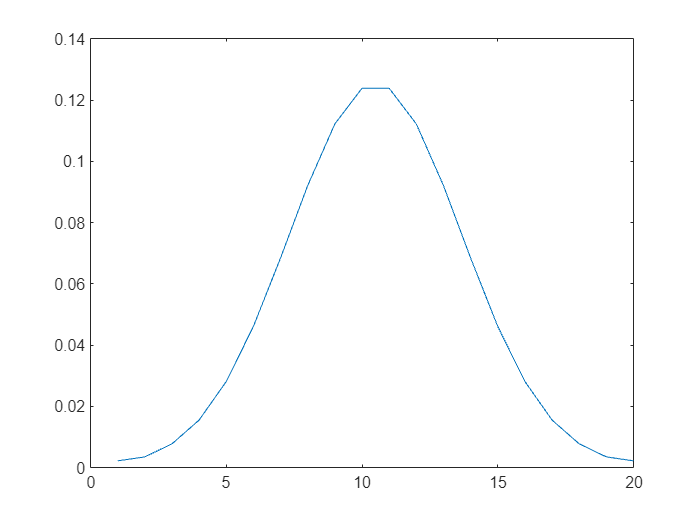

M = Zprob - eye(20);
M(:, 20) = ones(20,1);

c = zeros(20,1);
c(20) = 1;

pi = linsolve(M', c);

plot(pi)

c

%EV of k given beta = 0.9
dot(exp(1).^Z, pi)

ans = 0.1719


%EV of log(k)
dot(Z, pi)

ans = -1.7610


%EV of Log(k) using explicit formula
%(which is the unconditional mean)
(1/(1-alpha))*(log(alpha)+log(beta))

ans = -1.7610


%we now generalize this process 
% to find the expected values 
% for beta = 0.95, 0.97, 0.99


Comparing expected k at Different beta's (vt is simulated value, vi is explicit solution)

[vt, vi] = expected(0.95)

vt = 0.1870

vi = 0.1870

[vt, vi] = expected(0.97)

vt = 0.1932

vi = 0.1932

[vt, vi] = expected(0.99)

vt = 0.1995

vi = 0.1995

function for finding expected k at different beta (both simulated and theoretical)

function [vt, vi] = expected(b)
%parameters
alpha = 0.36;
beta = b;
sig = 0.01;

%input parameters
N = 20;
mu = (1/(1-alpha))*log(alpha*beta);
rho = alpha;
sigma = sig;
m = 3;

%Tauchen
[Z, Zprob] = tauchen(20,mu,rho, sigma,m);

M = Zprob - eye(20);
M(:, 20) = ones(20,1);

c = zeros(20,1);
c(20) = 1;

pi = linsolve(M', c);
vt = dot(exp(1).^Z, pi);
vi = exp(1)^(mu);
%+sig^2/(2*(1-alpha^2))
end